# Analog Communication Systems

# ***Basic Signals And Plotting***

## Clearing the workspace

close all;
clear;
clc;

## 1. Bases of Communication

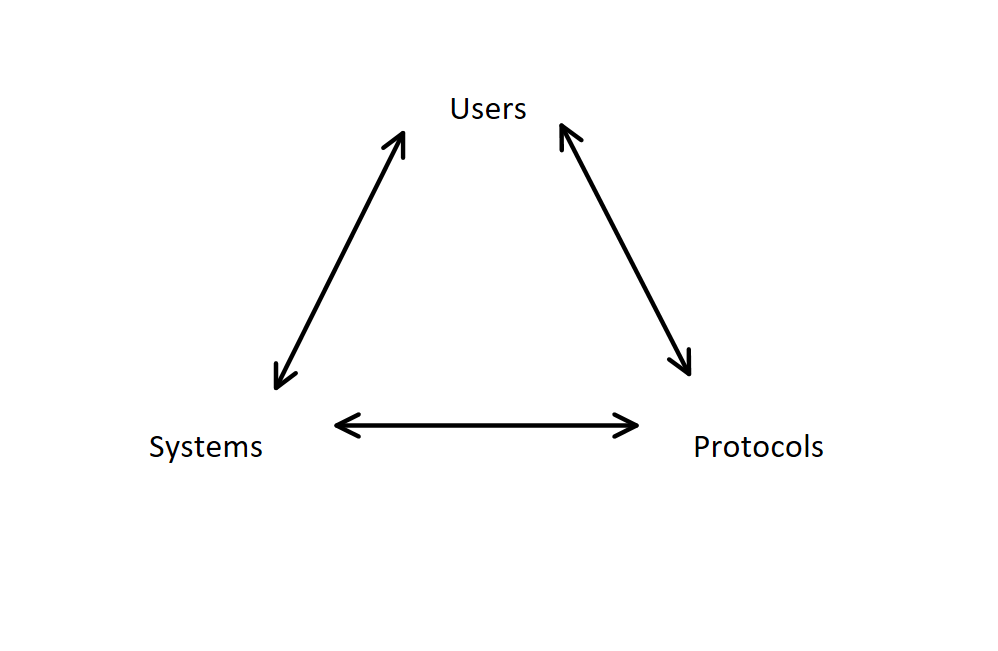

imshow("./images/communication-triangle.png")

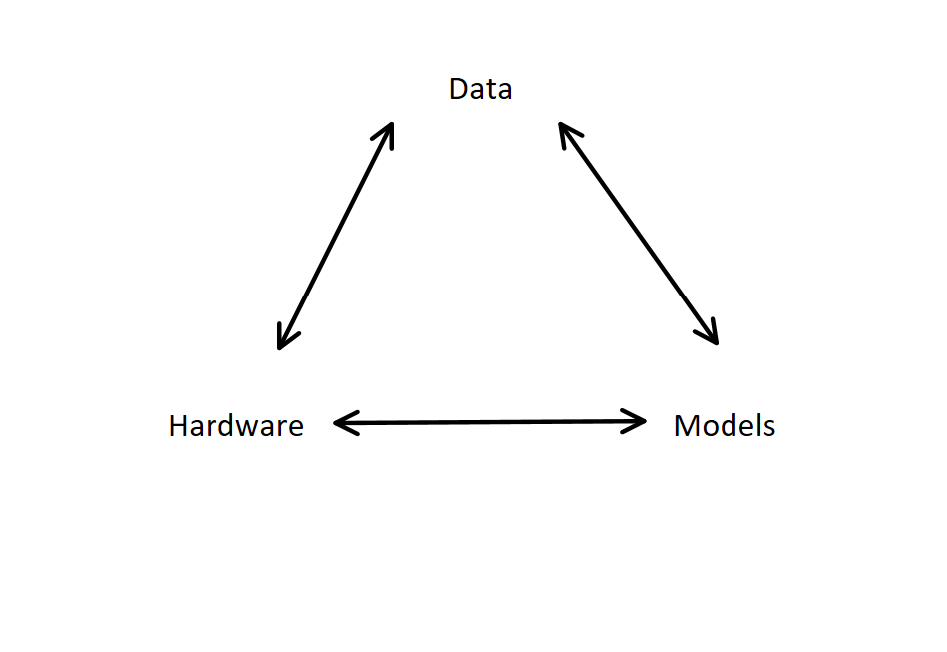

imshow("./images/machine-learning-triangle.png")

## 2. Workflow of Communication Systems

### Analog Communication Systems

In this course we will study analog communication systems. The workflow of communication systems is shown in the figure below. The first step is to generate the message signal. The message signal is then modulated to combine it with the carrier signal. The modulated signal is then transmitted over the channel. The receiver then demodulates the signal to recover the message signal.

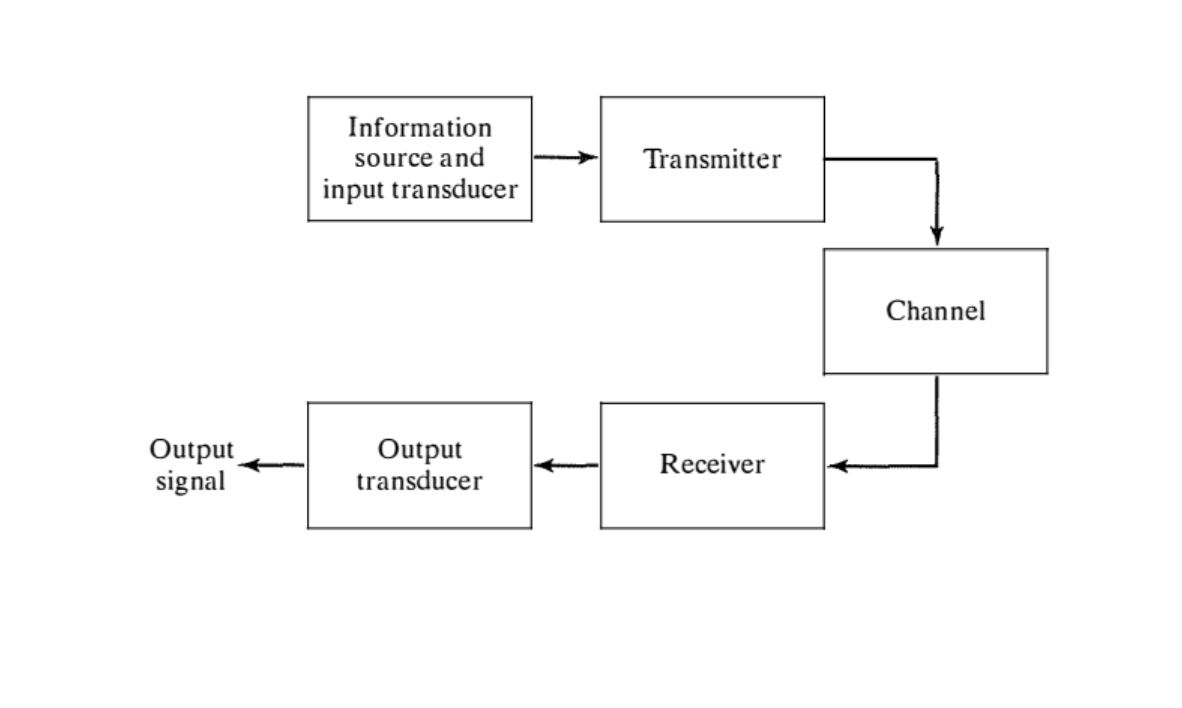

imshow("./images/analog-communication-system.png")

### Digital Communication Systems

In digital communication systems, the message signal is first converted to a digital signal. The digital signal is then modulated to combine it with the carrier signal. The modulated signal is then transmitted over the channel. The receiver then demodulates the signal to recover the digital signal. The digital signal is then converted back to the message signal.

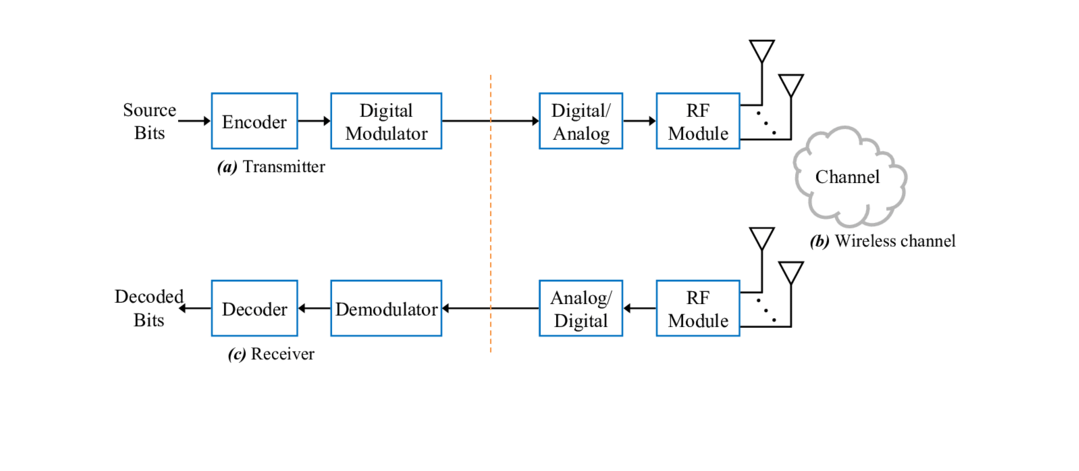

imshow("./images/digital-communication-system.png")

### The Final advanced workflow

The final advanced workflow of communication systems is shown in the figure below.

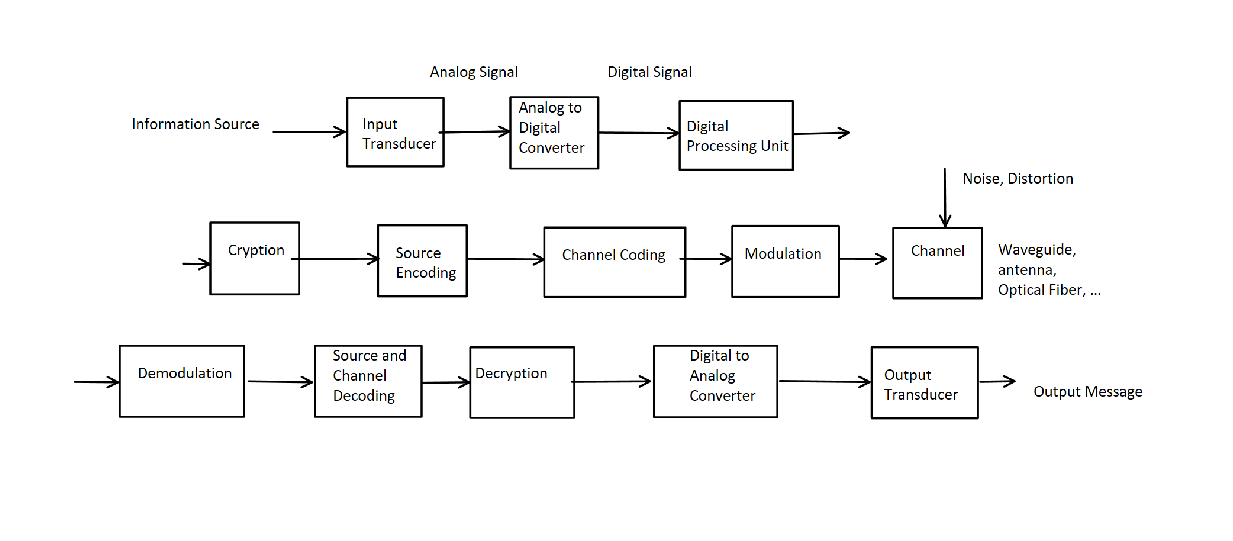

imshow("./images/communication-systems-workflow.png")

Digital Processing Unit $\to$w Digital Signal Processing

Cryption $\to$ Cryptography

Source Coding $\to$ Compression And Information Theory

Channel Coding $\to$ Error Correction Coding

Modulation $\to$ AM, FM, PM, QAM, PSK, QPSK, OFDM, MIMO, etc.

Channel $\to$ AWGN, Rayleigh, Rician, etc.

    (Including these courses: Fields and Waves, Microwave and Antenna, Radar Engineering, Optical Communication, etc.)

Receiver $\to$ Equalization, Detection, etc.

Filtering $\to$ Synthesis and Analysis of filters, etc.

Lots of users $\to$ Communication Networks

Data transfering $\to$ Data Transmission Systems

Designing communication systems $\to$ Electronics and Communication Circuits

## 3. Vectors and Matrices

Vectors are one dimensional arrays. Matrices are two dimensional arrays.

a = [1 2 3 4 5 6 7 8 9 10];
b = 1:10;
c = [1; 2; 3];
d = a';
e = 0:0.1:2;
length(e);

f = [1 2 3; 4 5 6; 7 8 9];
g = 1:9;
g = reshape(g, 3, 3);

disp(g(1));

     1



disp(g(1:4));

     1     2     3     4




h = ones(3, 3);
i = zeros(3, 3);
j = eye(3, 3);

a = 2:2:20;
size(a);
size(b);

b(a == 10) = 100;

## 4. Approximate Construction of continuous time signals

The time axis is the horizontal axis. The amplitude axis is the vertical axis.

fs = 1000;
Ts = 1 / fs;
t = 0:1 / fs:1;

x = sin(2 * pi * 10 * t);

## 5. Plotting signals

The plot function is used to plot signals. The plot function takes two arguments. The first argument is the time axis. The second argument is the signal to be plotted.

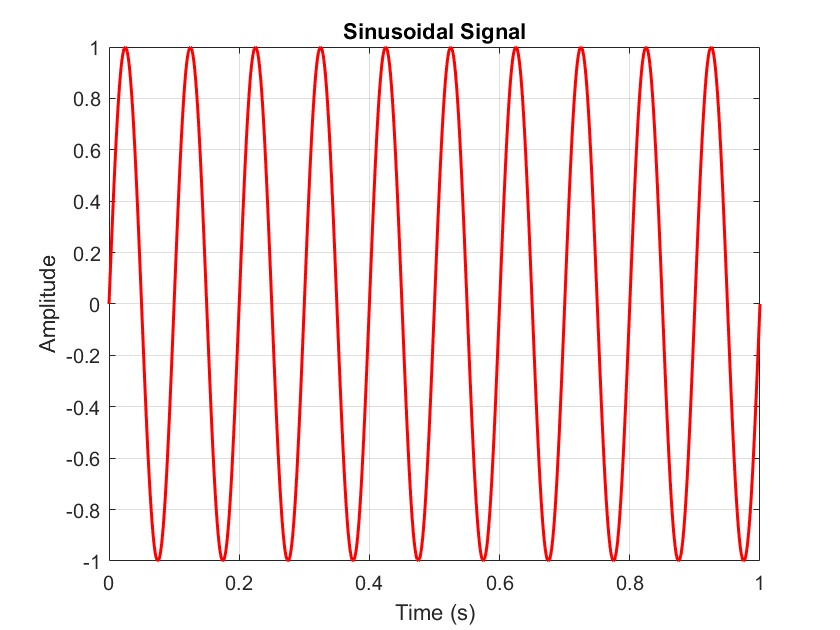

figure('Name', 'Siunusoidal Signal');
plot(t, x, 'LineWidth', 1.5, 'Color', 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Signal');
grid on;

### Holding function 

The plot function can also be used to plot multiple signals together. 

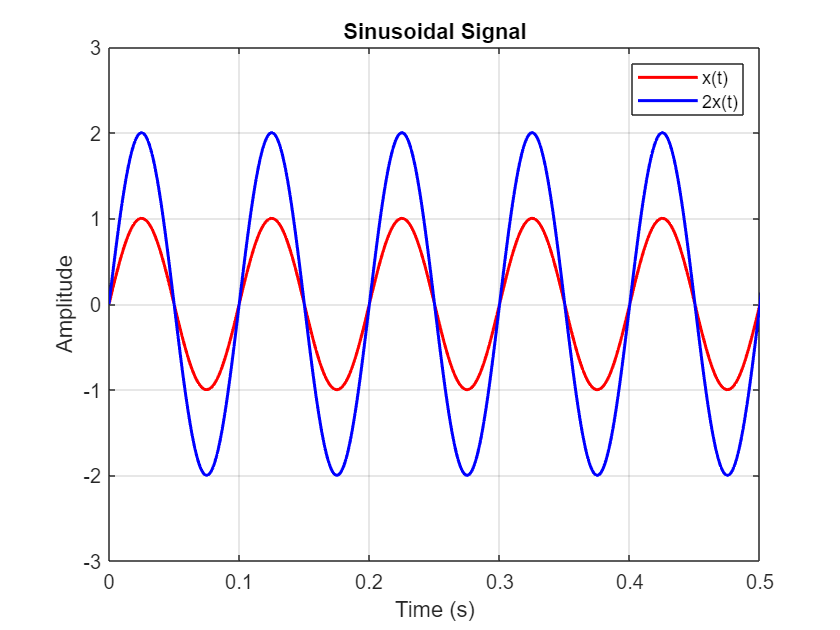

figure('Name', '2 Siunusoidal Signals');
plot(t, x, 'LineWidth', 1.5, 'Color', 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Signal');
grid on;
hold on;
plot(t, 2 * x, 'LineWidth', 1.5, 'Color', 'b');
xlim([0 0.5]);
ylim([-3 3]);
legend('x(t)', '2x(t)');

### Subplots

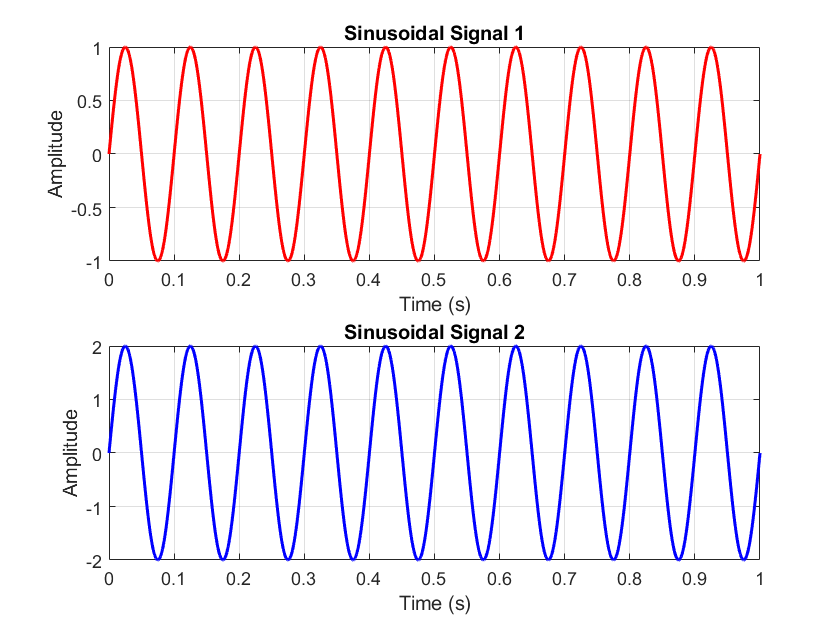

figure('Name', '2 Siunusoidal Signals');
subplot(2, 1, 1);
plot(t, x, 'LineWidth', 1.5, 'Color', 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Signal 1');
grid on;

subplot(2, 1, 2);
plot(t, 2 * x, 'LineWidth', 1.5, 'Color', 'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Signal 2');
grid on;

## 6. Reconstruction of a periodic continuous time signal using coefficient matrix

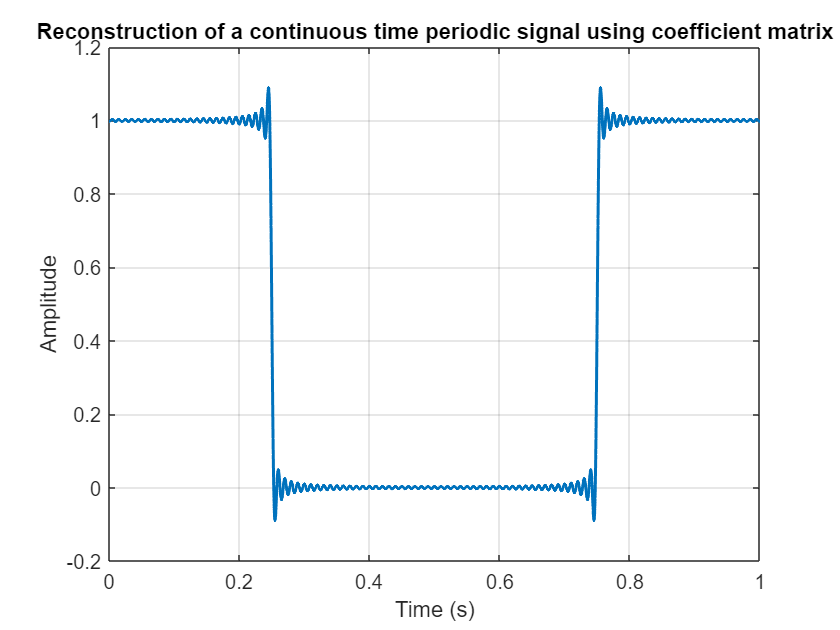

T0 = 1;
fs = 10000;
t = 0:1 / fs:1;
tau = 0.5;
N = 100;
n = -N:N;
a_n = (tau / T0) * sinc(n * tau / T0);
kernel = exp(1j * 2 * pi * n' * t / T0);
x = a_n * kernel;

figure('Name', 'Reconstruction of a continuous time periodic signal using coefficient matrix');
plot(t, real(x), 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Reconstruction of a continuous time periodic signal using coefficient matrix');
grid on;

- Increasing the N value will increase the accuracy of the reconstruction. However, increasing the N value will also increase the computational complexity of the reconstruction.

-  Increasing N will increase the higher frequency components of the signal.

- So we can use the Nyquist-Shannon sampling theorem to determine the value of fs.(fs >= 2 * N)

- If N is not high enough, the reconstruction will not be accurate and the Gibbs phenomenon won't be observed.

- At frequency fs = 2 * N, the signal is sampled at the Nyquist frequency. All of the oscillations of the signal are captured. but the signal is not very smooth.

## 7. Basic signals in communication systems

Delta function The delta function is a function that is zero everywhere except at the origin. The delta function is used to represent the impulse response of systems. The delta function is also used to represent the Dirac comb function.

### Delta function

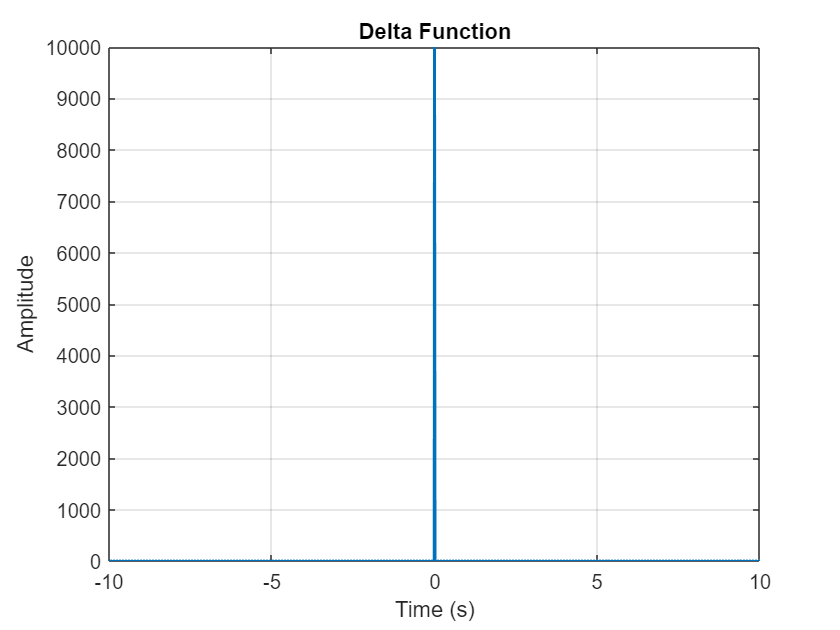

fs = 1e4;
t = -10:1 / fs:10;

% delta = t;
% delta(t == 0) = fs;

delta = dirac(t);
delta(delta == Inf) = fs;

figure('Name', 'Delta Function');
plot(t, delta, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Delta Function');
grid on;

### Dirac comb function

The Dirac comb function is a periodic function that is zero everywhere except at the integer multiples of the period. The Dirac comb function is used to represent the periodic impulse response of systems.

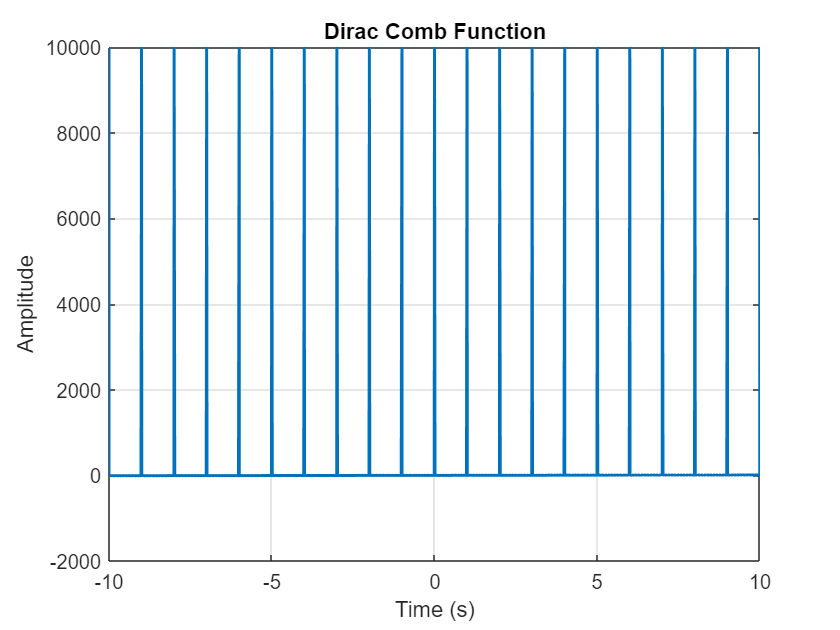

figure('Name', 'Dirac Comb Function');
dirac_comb = t;
dirac_comb(mod(t, 1) == 0) = fs;
plot(t, dirac_comb, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Dirac Comb Function');
grid on;

### Unit step function

The unit step function is a function that is zero for all negative values and one for all positive values. The unit step function is used to represent the step response of systems.

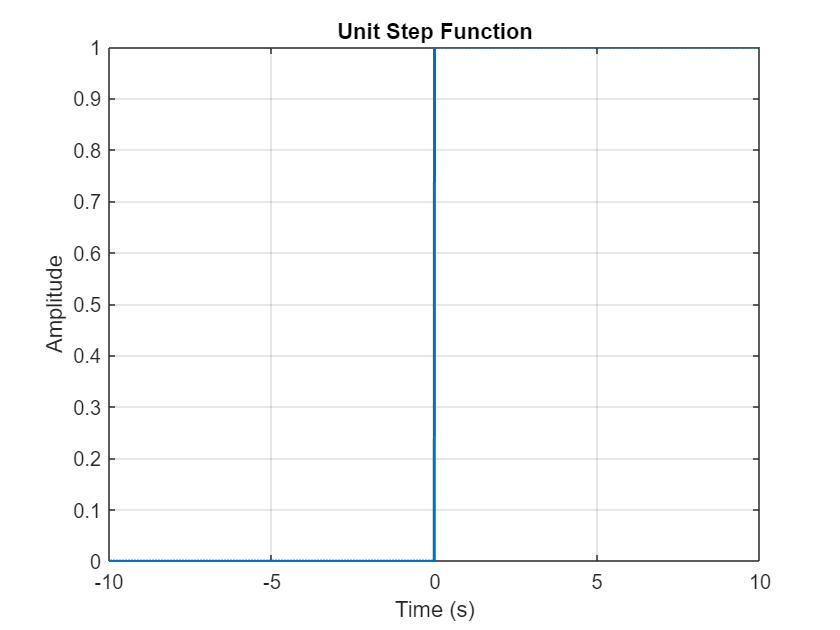

unit_step = heaviside(t);
% unit_step = zeros(1, length(t));
% unit_step(t > 0) = 1;

figure('Name', 'Unit Step Function');
plot(t, unit_step, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Unit Step Function');
grid on;

### Square wave

The square wave is a periodic function that is one for half of the period and zero for the other half of the period. The square wave is used to represent the periodic step response of systems.

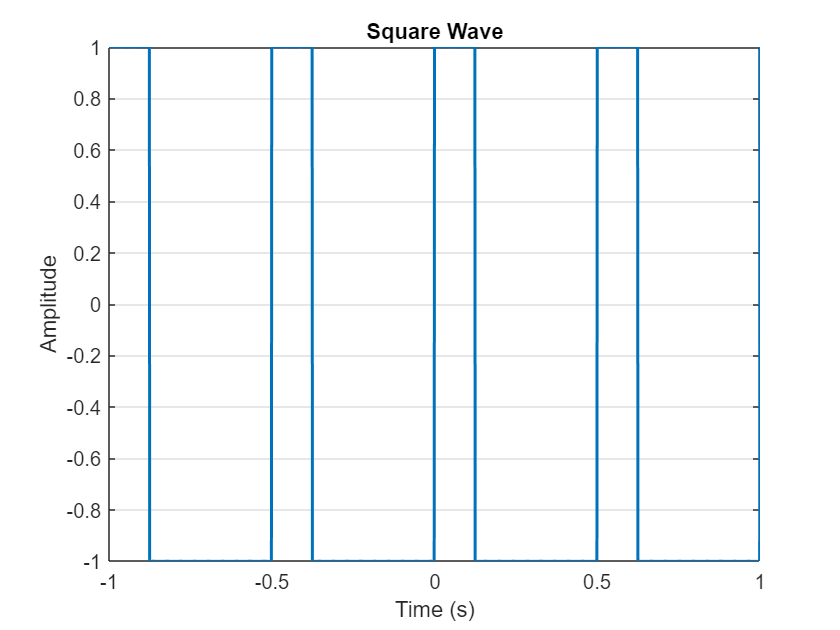

fs = 1e3;
t = -1:1 / fs:1;
T0 = 0.5;
duty_cycle = 0.25;
square_wave = square(2 * pi * t / T0, duty_cycle * 100);

figure('Name', 'Square Wave');
plot(t, square_wave, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Square Wave');
grid on;

### Square pulse

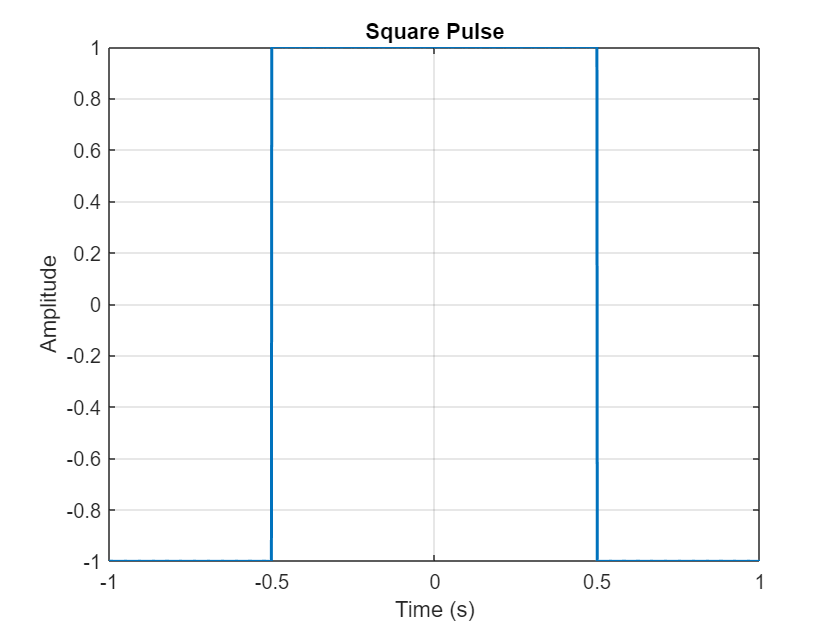


t = -1:1 / fs:1;
T0 = 2;
duty_cycle = 0.5;
square_wave = square(2 * pi * (t + 0.5) / T0, duty_cycle * 100);

figure('Name', 'Square Pulse');
plot(t, square_wave, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Square Pulse');
grid on;

### Sawtooth wave

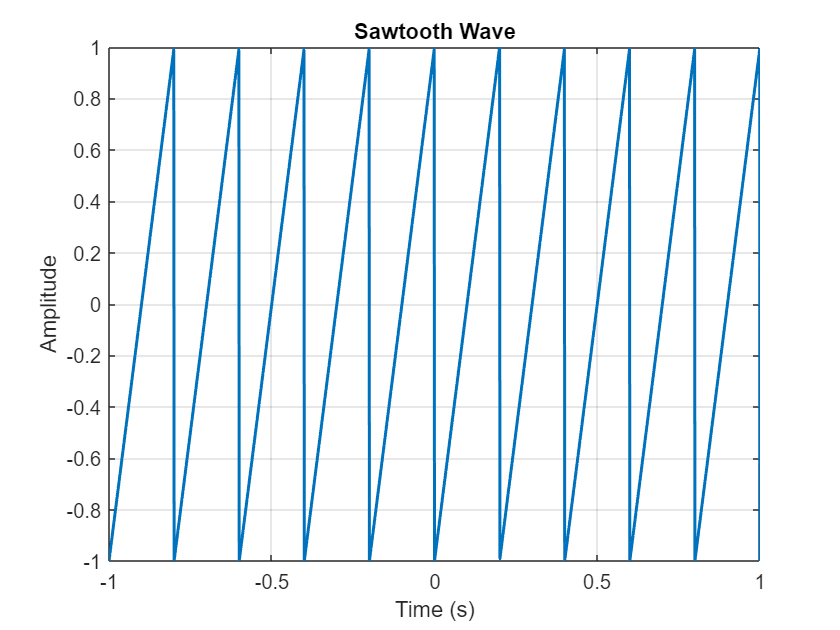

T0 = 0.2;
sawtooth_wave = sawtooth(2 * pi * t / T0);

figure('Name', 'Sawtooth Wave');
plot(t, sawtooth_wave, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sawtooth Wave');
grid on;

## 8. Discrete time signals

Discrete time signals are signals that are sampled at discrete time instants. The sampling rate of discrete time signals is called the sampling frequency. The sampling frequency is denoted by fs. The sampling frequency is the number of samples per second. The sampling frequency is the reciprocal of the sampling period. The sampling period is the time between two consecutive samples. The sampling period is denoted by Ts.

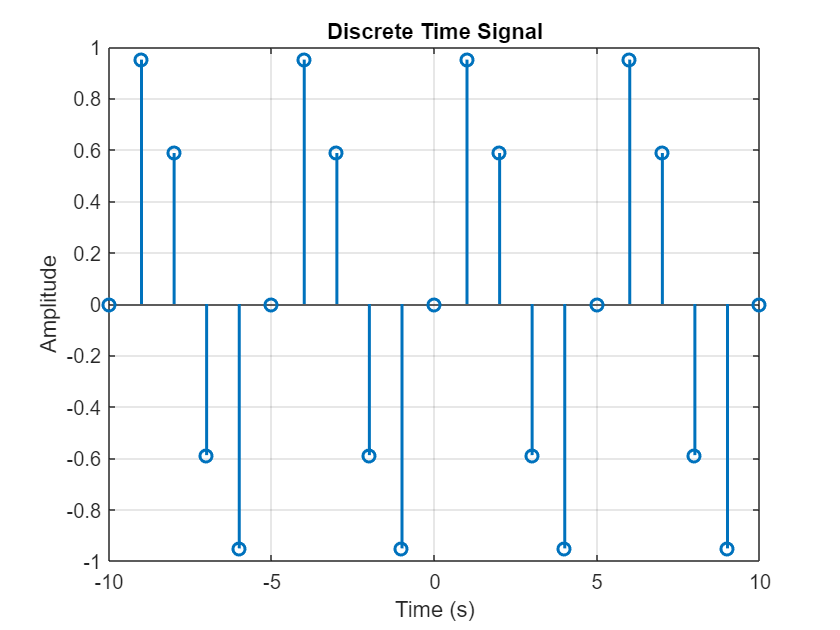

n = -10:10;
x = sin(2 * pi * n / 5);

figure('Name', 'Discrete Time Signal');
stem(n, x, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Discrete Time Signal');
grid on;